clc
clear all
close all

In this code we compute the equally weighted portfolio, we compute the risk contributions of every asset. We build the Equally weighted, Risk Parity, Most diversified and Minimum Variance Portfolios and plot the equity curves to compare. The, we compute the metrics for all. 

**Read Prices**

load myPrice_dt.mat
load array_prices

**Selection of a subset of Dates**

start_dt = datetime('01/01/2021', 'InputFormat', 'dd/MM/yyyy');
end_dt = datetime('01/01/2022', 'InputFormat', 'dd/MM/yyyy');

rng = timerange(start_dt, end_dt, 'closed');
subsample = myPrice_dt(rng, 1);
dates_ = subsample.Time;

**Calculate returns and Covariance Matrix**

LogRet = tick2ret(prices_val, 'Method', 'Continuous');
ExpRet = mean(LogRet);
CovMatrix = cov(LogRet);

**Equally weighted Ptf**

wEW = 1/size(LogRet,2)*ones(15,1);
RetPtfEW = wEW'*ExpRet';
VolaPtfEW = sqrt(wEW'*CovMatrix*wEW);

**Risk Contribution of EW Ptf**

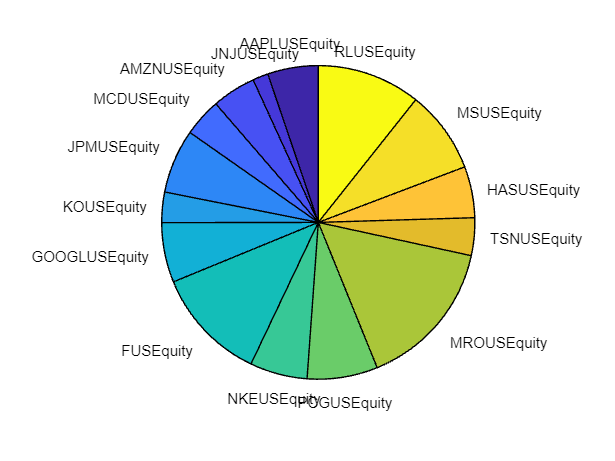

[relRC_ew, RC_ew, mVol_ew] = getRiskContribution(wEW, LogRet);

pie(relRC_ew, assetNames)

**Risk Parity**

Target = wEW;
Aeq = ones(1,15);
beq = 1;
lb = zeros(1,15);
ub = ones(1,15);
x0 = zeros(15,1);
x0(1,1) = 1;
w_RP = fmincon(@(x) mse_risk_contribution(x, LogRet, Target), x0, [], [], Aeq, beq, lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



[relRC_rp, RC_rp, mVol_rp] = getRiskContribution(w_RP, LogRet);

**Plot**

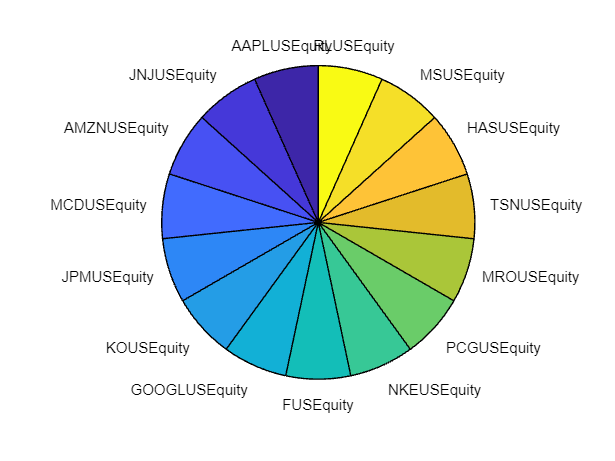

figure;
title('Relative Risk Contribution For Risk Parity')
pie(relRC_rp, assetNames)

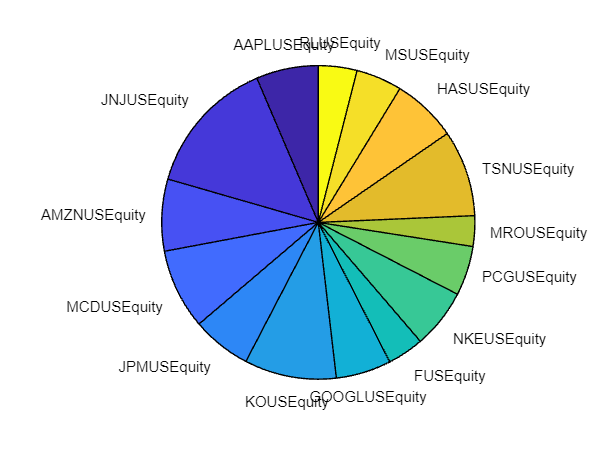

figure;
title('Weights For Risk Parity')
pie(w_RP, assetNames)

**Most Diversified Portfolio**

DR_ew = getDiversificationRatio(wEW, LogRet);
DR_rp = getDiversificationRatio(w_RP, LogRet);

**Maximization of DR**

Aeq = ones(1,15);
beq = 1;
lb = zeros(1,15);
ub = ones(1,15);
x0 = zeros(15,1);
x0(1,1) = 1;

[w_DR, fval] = fmincon(@(x) -getDiversificationRatio(x, LogRet), x0, [], [], Aeq, beq, lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


MaxDR = -fval;

**Max Entropy (weights)**

EntropyEW = getEntropy(wEW);
EntropyRP = getEntropy(w_RP);
EntropyDR = getEntropy(w_DR);

**Optimization**

Aeq = ones(1,15);
beq = 1;
lb = zeros(1,15);
ub = ones(1,15);
x0 = zeros(15,1);
x0(1,1) = 1;
w_MaxEntropy = fmincon(@(x) -getEntropy(x), x0, [], [], Aeq, beq, lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


**Max Entropy in Risk Contribution**

w_MaxEntropyRisk = fmincon(@(x) -getEntropy(getRiskContribution(x, LogRet)), x0, [], [], Aeq, beq, lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


**Max Entropy Volatilities**

w_MaxEntropyVol = fmincon(@(x) -getEntropy(getVolContribution(x,LogRet)), x0, [], [], Aeq, beq, lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


**Minimum Variance Portfolio**

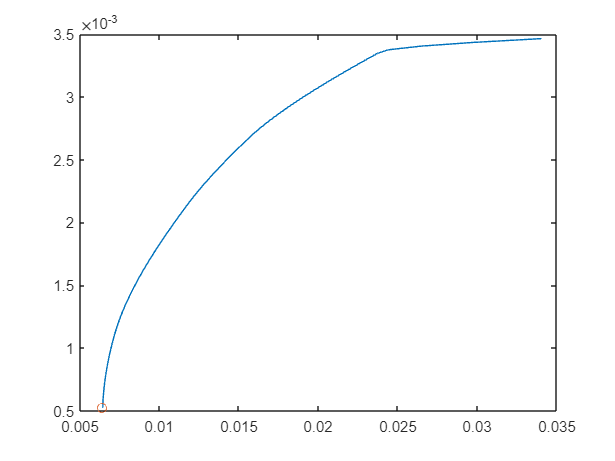

p = Portfolio('AssetList', assetNames);
p = setDefaultConstraints(p);
PortMV = estimateAssetMoments(p, LogRet, 'MissingData', false);
weightsMVP = estimateFrontier(PortMV, 100);
[pfMVP_Risk, pfMVP_Retn] = estimatePortMoments(PortMV, weightsMVP);

[min_vola, indexMV] = min(pfMVP_Risk);

figure;
plot(pfMVP_Risk, pfMVP_Retn)
hold on
scatter(min_vola, weightsMVP(:,indexMV)'*ExpRet')

**Compare Portfolios (EW, RP, MD, EntropyVol) - In Sample**

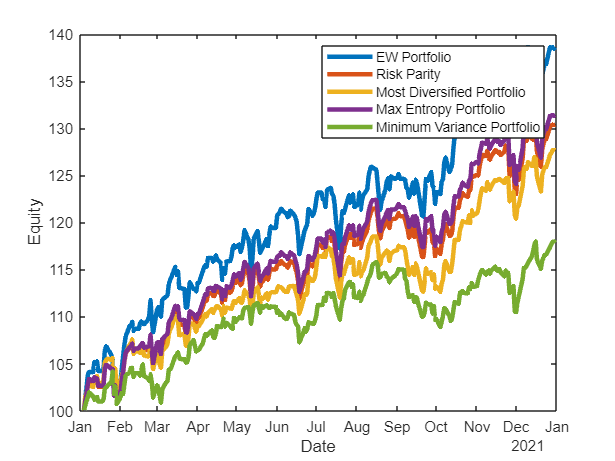

ret = prices_val(2:end,:)./prices_val(1:end-1,:);
%Equity curve
equityEW = cumprod(ret*wEW);
%force the equity to start from the same value
equityEW = 100.*equityEW/equityEW(1);
%RP
equityRP = cumprod(ret*w_RP);
equityRP = 100.*equityRP/equityRP(1);
%Most Diversified
equityMD = cumprod(ret*w_DR);
equityMD = 100.*equityMD/equityMD(1);
%Entropy Vol Ptf
equityEVol = cumprod(ret*w_MaxEntropyVol);
equityEVol = 100.*equityEVol/equityEVol(1);
%Minimum Variance Portfolio
equityMVP = cumprod(ret*weightsMVP(:,indexMV));
equityMVP = 100.*equityMVP/equityMVP(1);

%Plot
figure;
plot(dates_(2:end, 1), equityEW, 'LineWidth', 3)
hold on
plot(dates_(2:end, 1), equityRP, 'LineWidth', 3)
plot(dates_(2:end, 1), equityMD, 'LineWidth', 3)
plot(dates_(2:end, 1), equityEVol, 'LineWidth', 3)
plot(dates_(2:end, 1), equityMVP, 'LineWidth', 3)
legend('EW Portfolio', 'Risk Parity','Most Diversified Portfolio', 'Max Entropy Portfolio', 'Minimum Variance Portfolio')
xlabel('Date')
ylabel('Equity')

**Performance Metrics**

[annRet_ew, annVol_ew, Sharpe_ew, MaxDD_ew, Calmar_ew] = getPerformanceMetrics(equityEW);
[annRet_rp, annVol_rp, Sharpe_rp, MaxDD_rp, Calmar_rp] = getPerformanceMetrics(equityRP);
[annRet_md, annVol_md, Sharpe_md, MaxDD_md, Calmar_md] = getPerformanceMetrics(equityMD);
[annRet_ev, annVol_ev, Sharpe_ev, MaxDD_ev, Calmar_ev] = getPerformanceMetrics(equityEVol);
[annRet_mv, annVol_mv, Sharpe_mv, MaxDD_mv, Calmar_mv] = getPerformanceMetrics(equityMVP);

metricsEW = [annRet_ew; annVol_ew; Sharpe_ew; MaxDD_ew; Calmar_ew];
metricsRP = [annRet_rp; annVol_rp; Sharpe_rp; MaxDD_rp; Calmar_rp]; 
metricsMD = [annRet_md; annVol_md; Sharpe_md; MaxDD_md; Calmar_md];
metricsEVol = [annRet_ev; annVol_ev; Sharpe_ev; MaxDD_ev; Calmar_ev];
metricsMV = [annRet_mv; annVol_mv; Sharpe_mv; MaxDD_mv; Calmar_mv];

metrics_ = ["AnnRet"; "AnnVol"; "Sharpe Ratio"; "MaxDD"; "Calmar Ratio"];
table(metrics_, metricsEW, metricsRP, metricsMD, metricsEVol, metricsMV, 'VariableNames', ["Metrics", "EW", "RP", "MD", "Entropy Vol", "Minimum Variance"])

ans = 5×6 table
       Metrics           EW           RP           MD        Entropy Vol    Minimum Variance
    ______________    _________    _________    _________    ___________    ________________

    "AnnRet"            0.37235      0.29317        0.267         0.303          0.17217    
    "AnnVol"            0.14278      0.11992      0.11684       0.12287          0.10091    
    "Sharpe Ratio"       2.6078       2.4447       2.2852         2.466           1.7061    
    "MaxDD"           -0.052316    -0.042848    -0.049822     -0.041599        -0.060155    
    "Calmar Ratio"       7.1172       6.8423       5.3591        7.2839           2.8621    
